This system is controllable!


K =    -0.2067   -0.5500   15.2365    1.0702


ans =     0.9076
    0.9330
    0.9954
    0.9885


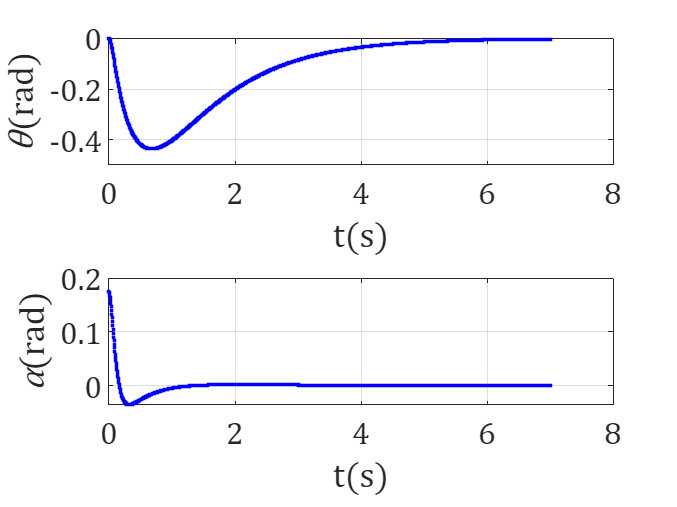

clc
set(groot,'defaultLineLineWidth',2,'defaultAxesFontName','Cambria Math','defaultAxesFontSize',20,'defaultLegendFontName','Cambria Math','defaultLegendFontSize',20)
m = 0.140; % mass of pendulum
l = 0.135/2; % The distance from the center of mass of the pendulum to the axis of rotation
J = 1/3*m*((0.135/2)^2+(0.018)^2); % Moment of inertia when the pendulum rotates around the center of mass
g = 9.8; % acceleration due to gravity
R = 4.286; % armature resistance
r = 0.156; % length of the rotating arm
K_m = 0.1797; % Electromagnetic torque coefficient
K_e = 0.2087; % back EMF coefficient
I = 1/3*m*((0.135/2)^2+(0.018)^2)+m*(0.135/2)^2;% Moment of inertia when the rotating arm rotates around the motor shaft
Q_eq = I*J+I*m*l^2+J*m*r^2;
A_22 = -(K_m*K_e*(J+m*l^2))/(Q_eq*R);
A_23 = (m^2*l^2*r*g)/Q_eq;
A_42 = -(m*r*l*K_m*K_e)/(Q_eq*R);
A_43 = (m*g*l*(I+m*r^2))/Q_eq;
B_21 = (K_m*(J+m*l^2))/(Q_eq*R);
B_41 = (m*r*l*K_m)/(Q_eq*R);
A = [0 1 0 0; 0 A_22 A_23 0; 0 0 0 1; 0 A_42 A_43 0];
B = [0; B_21; 0; B_41];
C = [1 0 0 0; 0 0 0 0; 0 0 1 0; 0 0 0 0];
D = [0 0 0 0]';
Ts = 0.005; % sampling interval
t = 0:Ts:7;
u = zeros(size(t));
[G,H] = c2d(A,B,Ts); % change the continuous system into a discrete system
x0 = [0; 0; 0.1745; 0]; % set the initial state of the system
Tc = ctrb(G,H);
if (rank(Tc)==4)
fprintf('This system is controllable!\n');
Q = [50 0 0 0; 0 25 0 0; 0 0 50 0; 0 0 0 10];
R = 1000;
K = dlqr(G,H,Q,R) % Calculate the state feedback coefficient
G2 = G-H*K;
eig(G2)

y = dlsim(G2,H,C,D,u,x0);

figure()
subplot(2,1,1)
plot(t,y(:,1),'b.');
xlabel('t(s)');
ylabel('\theta(rad)');
grid on
subplot(2,1,2)
plot(t,y(:,3),'b.');
xlabel('t(s)');
ylabel('\alpha(rad)');
grid on
end

[b,a] = ss2tf(A,B,C,D)

b = 1.0e+03 *

         0         0    0.0238   -0.0000   -2.5458
         0         0         0         0         0
         0         0    0.0405    0.0000    0.0000
         0         0         0         0         0


a =     1.0000    4.9660 -259.4297 -531.2998         0


TF1=tf(b(1,:),a) % Angulo brazo giratorio / ua

TF1 =
 
      23.8 s^2 - 2.959e-13 s - 2546
  -------------------------------------
  s^4 + 4.966 s^3 - 259.4 s^2 - 531.3 s
 
Continuous-time transfer function.
Model Properties


TF2=tf(b(3,:),a) % Angulo de pendulo / ua

TF2 =
 
   40.52 s^2 + 1.788e-13 s + 9.764e-15
  -------------------------------------
  s^4 + 4.966 s^3 - 259.4 s^2 - 531.3 s
 
Continuous-time transfer function.
Model Properties


TF1zpk=zpk(TF1)

TF1zpk =
 
    23.795 (s-10.34) (s+10.34)
  -------------------------------
  s (s+17.84) (s-14.88) (s+2.002)
 
Continuous-time zero/pole/gain model.
Model Properties


TF2zpk=zpk(TF2)

TF2zpk =
 
     40.524 (s^2 + 2.409e-16)
  -------------------------------
  s (s+17.84) (s-14.88) (s+2.002)
 
Continuous-time zero/pole/gain model.
Model Properties



TF1_2nd=zpk(balred(TF1,2))

TF1_2nd =
 
  -2.3174 (s-15.04) (s-2.045)
  ---------------------------
          s (s-14.88)
 
Continuous-time zero/pole/gain model.
Model Properties


TF2_2nd=zpk(balred(TF2,2))

TF2_2nd =
 
  0.073395 (s^2 + 3.725e-15)
  --------------------------
         s (s-14.88)
 
Continuous-time zero/pole/gain model.
Model Properties


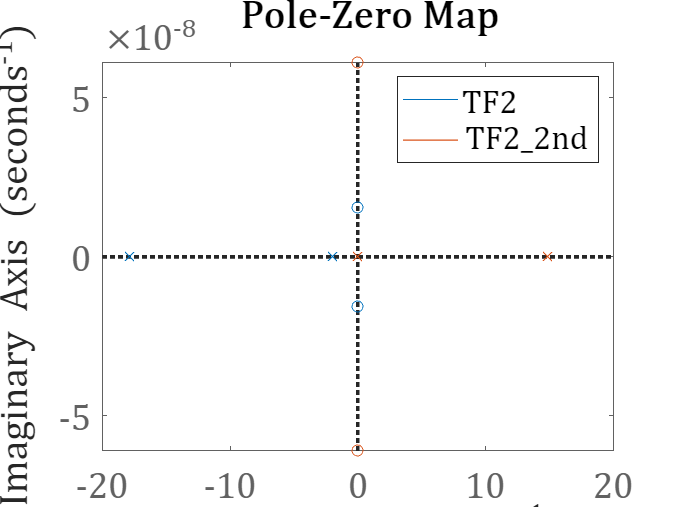



figure
pzmap(TF2)
hold on
pzmap(TF2_2nd)
legend

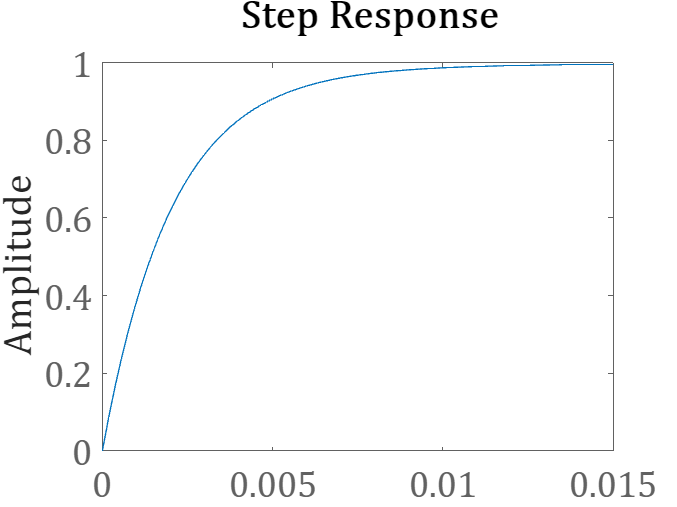


figure
step(feedback(pid(6,0,12)*TF2,1)) % PD con KP=6 y KD=12 (Arduino)

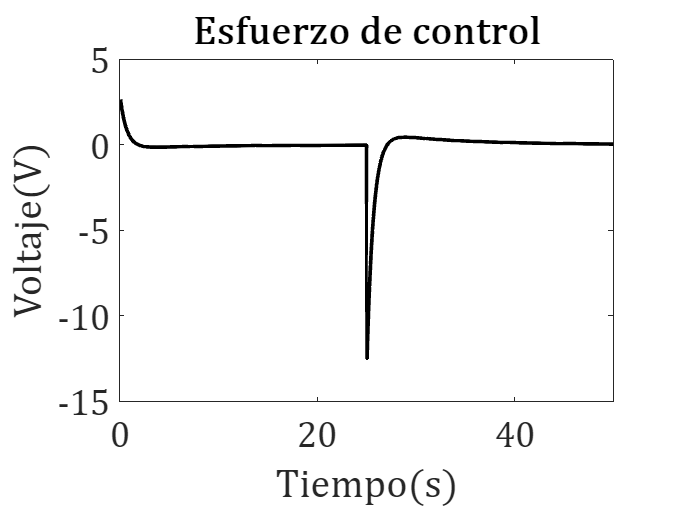

clear x up
x(:,1) = [0 0 -10*(2*pi)/360 0]';
for i = 1:1001
    if i == 500
        up(i) = -K * x(:, i);
        x(:, i + 1) = G * x(:, i) + H * up(i) + 0.8; %Perturbación
    else
        up(i) = -K * x(:, i);
        x(:, i + 1) = G * x(:, i) + H * up(i);
    end
end
tsim=0:0.05:50.05;

figure ()
plot(tsim(2:end), up,'k')
xlim([0 50])
title('Esfuerzo de control')
xlabel('Tiempo(s)');
ylabel('Voltaje(V)');
saveas(gcf, 'Esfuerzo.jpg');

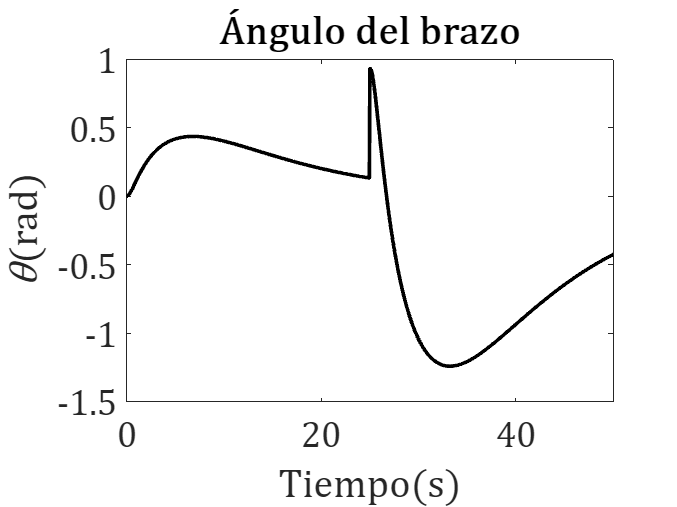


figure ()
plot(tsim, x(1,:),'k')
xlim([0 50])
title('Ángulo del brazo')
xlabel('Tiempo(s)');
ylabel('\theta(rad)');
saveas(gcf, 'AnguloB.jpg');

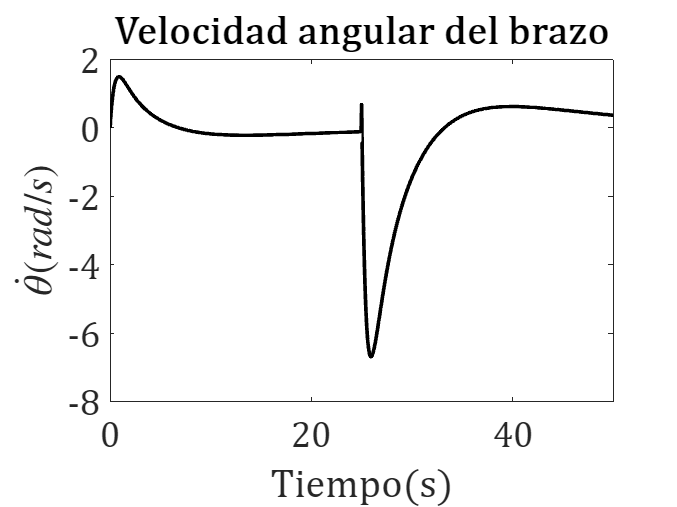


figure ()
plot(tsim, x(2,:),'k')
xlim([0 50])
title('Velocidad angular del brazo')
xlabel('Tiempo(s)');
ylabel('$ \dot{\theta} (rad/s)$','interpreter','latex');
saveas(gcf, 'VelB.jpg');

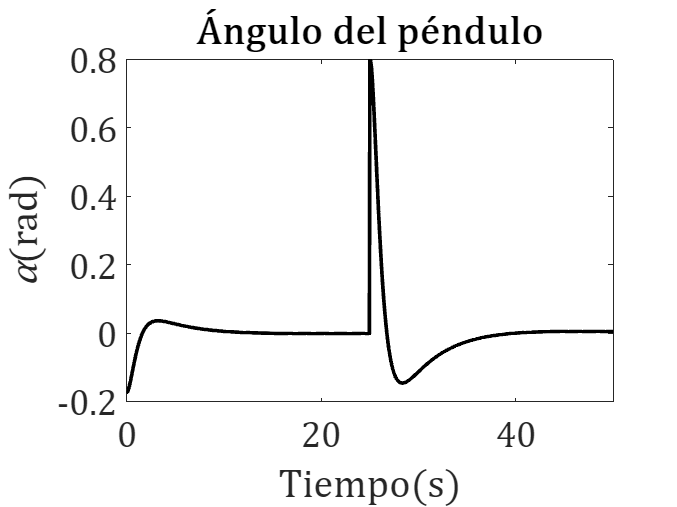


figure()
plot(tsim, x(3,:),'k')
xlim([0 50])
title('Ángulo del péndulo')
xlabel('Tiempo(s)');
ylabel('\alpha(rad)');
saveas(gcf, 'AnguloP.jpg');

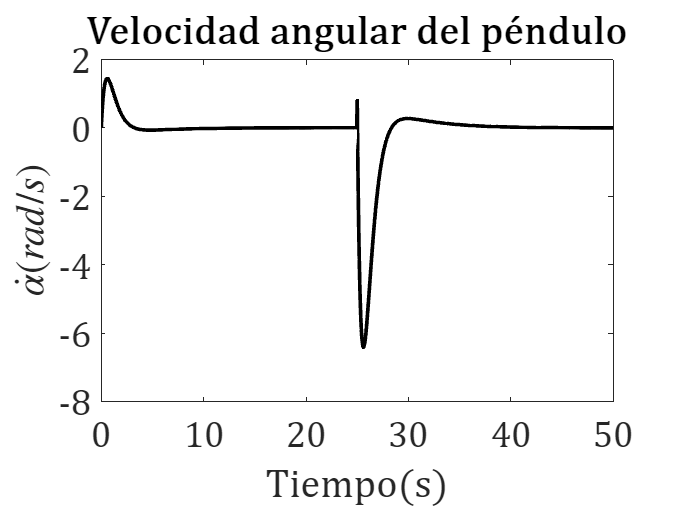


figure()
plot(tsim, x(4,:),'k')
xlim([0 50])
title('Velocidad angular del péndulo')
xlabel('Tiempo(s)');
ylabel('$ \dot{\alpha} (rad/s)$','interpreter','latex');
saveas(gcf, 'VelP.jpg');

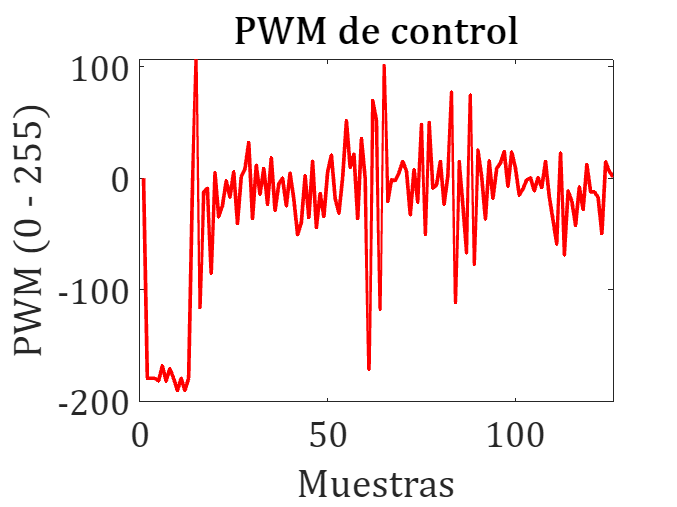

load('DatosPracticos.mat')

figure ()
plot(PWMMotor,'r')
xlim([0 length(PWMMotor)])
title('PWM de control')
xlabel('Muestras');
ylabel('PWM (0 - 255)');
saveas(gcf, 'PWMMotor.jpg');

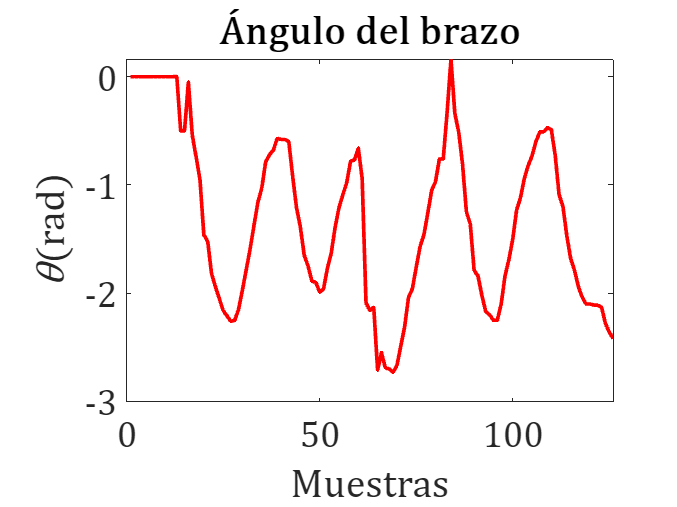


figure ()
plot(AnguloBrazo,'r')
xlim([0 length(PWMMotor)])

title('Ángulo del brazo')
xlabel('Muestras');
ylabel('\theta(rad)');
saveas(gcf, 'AnguloBrazo.jpg');

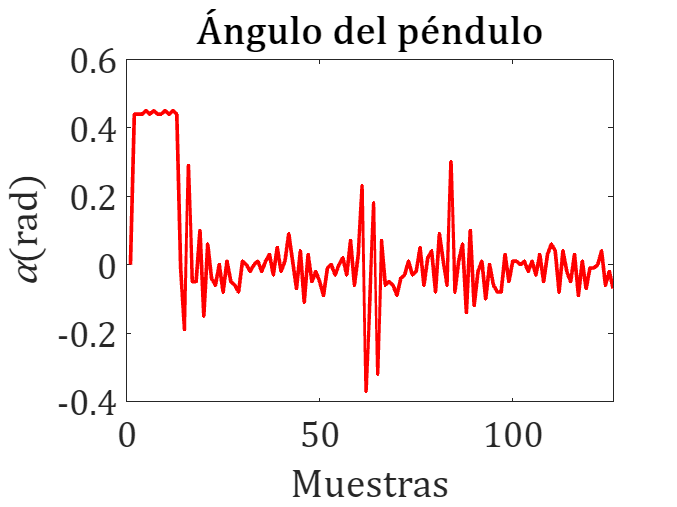


figure()
plot(AnguloPendulo,'r')
xlim([0 length(PWMMotor)])

title('Ángulo del péndulo')
xlabel('Muestras');
ylabel('\alpha(rad)');
saveas(gcf, 'AnguloPendulo.jpg');